# Euclidean Distance Mapping - 2Pass Sequential Algorithm

A 2-Pass sequential Euclidean distance mapping algorithm from the book, [Binary Digital Image Processing: A Discrete Approach.](file:///home/lms/workspace/distance_functions_matlab/euclidean_distance/docs/binary_digital_image_processing.bib)

## Create a sample binary image

- Create an image of size 8X7, contaning ones (foreground pixels). And two pixels at the center having zero values. 

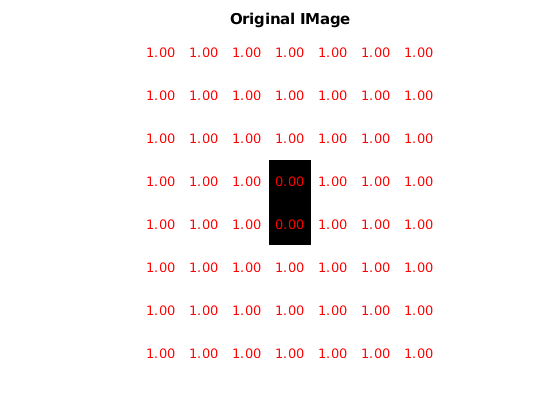

close all, clear;
img =logical(ones(8,7));
[m,n] = size(img);
img(ceil(m/2),ceil(n/2)) = 0;
img(ceil(m/2 + 1),ceil(n/2)) = 0;
show_pixels(img)
title("Original IMage")

## Create and initialize the distance map

- Create a cell structure to store the indipendent x and y distances as arryays [x,y]

- Initialize the distance map using: $DT^{(0)}_D = 
	\begin{cases}
		(0,0), &\text{if} p \in \Gamma \\
		(+\infty,+\infty), &\text{if} p \notin \Gamma
	\end{cases}$ 

dist = cell(m,n);
dist(~img) = {[0,0]};
dist(img) = {[Inf,Inf]};

- Create a $3 \times 3$ $(8-N)$distance mask where each value in the matrix $(m_{k,i})_{k,i}$ represents a local distance  between a pixel $p=(x_p,y_p)$and a neighbouring pixel $q=(x_p+k,y_p+l)$. A typical $8-N$ euclidian distance mas looks like this.

                                                                                         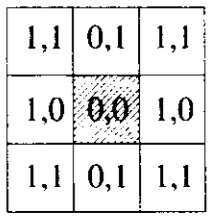

edm_8 = cell(3,3);
for i = 1:3
    for j = 1:3
        edm_8(i,j) = {[(mod(i,2)),mod(j,2)]};
    end
end
mask = zeros(3,3);
for i = 1:3
    for j = 1:3
        mask(i,j) = norm(edm_8{i,j});
    end
end

The cell array neighborhood stores the $x$ and $y$ coordinates separately.

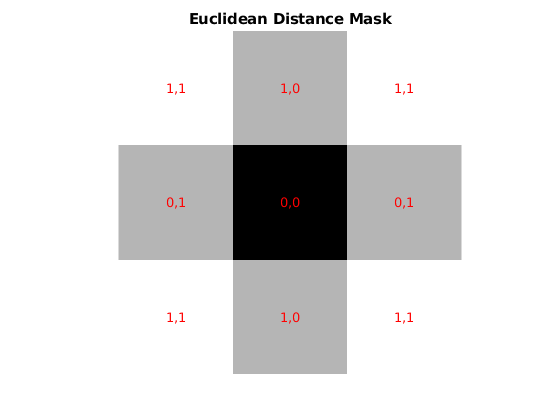

show_Edist(mask,edm_8)

title("Euclidean Distance Mask")

The actual pixel value could be retrieved using the definition of Euclidean distance. $DT_E(p) = ||EDT(p)||_2 = \sqrt{\delta_x(p)^2 + \delta_y(p)^2}$

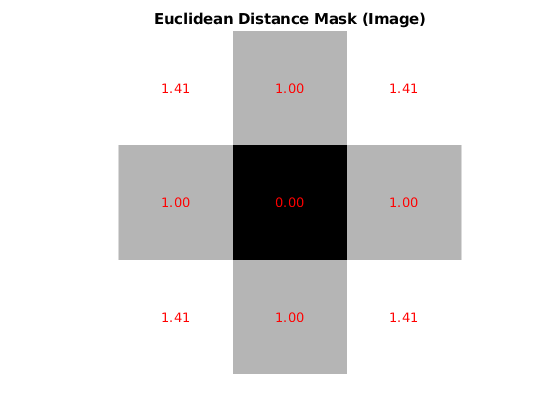

show_pixels(mask)

title("Euclidean Distance Mask (Image)")

## Updating rule:

- $	EDT^{(t)}(p) = EDT^{(t-1)}(q) + (|x_q - x_p|,|y_q - y_p|)$, where $q$ characterizes the minimum value of all the distances from each neighborhood pixel to the center pixel given by: $q \Rightarrow \min{\|EDT^{(t-1)}(q') + (|x_{q'} - x_p|,|y_{q'} - y_p|)\|}_2$

- the $min\|.\|$operator for the neighborhood should also consider the value of $p$ itself. We should make sure that we are propagating the minimum distance. This becomes important when updating pixels of the distance map containing values other thatn $\infty$. 

- The updating (propagation) procedurre is carreid out in two passes.

## Pass 1 - Upward Sequential Pass

The distance map is scanned line by line from the bottom line to the top line using three different **sub-masks**. For each line, all three sub-masks whose union is the lower half of the complete Euclideean mask are used successively. 

- The sub-mask (A) is first applied successively from left to right at each pixel of the current line.

- The sub-mask (B) is applied successively from left to right at each pixel of the current line. 

- The sub-mask © is applied successively from right to left at each pixel of the current line. 

                                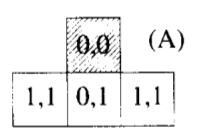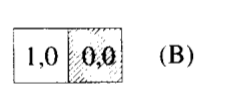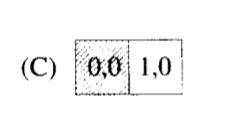

**Scan each line bottom to top.**

for i = m:-1:1

**First update (A)**

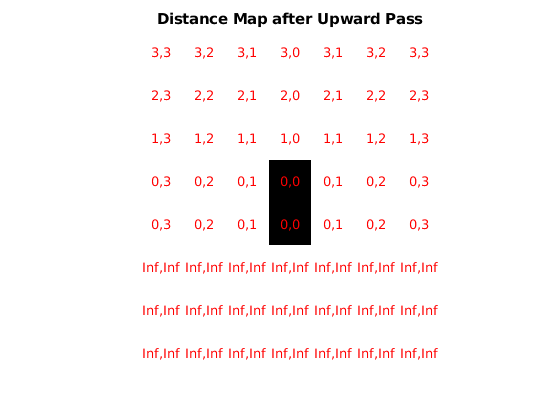

    for j = 1:n

        vals = [];
        if(img(i,j))
            if i == m
                
            elseif j == 1
                for k = 1:2
                    vals = [vals,norm(dist{i+1,j-1+k}+edm_8{3,k+1})];
                end
                [minVal,idx] = min(vals);
                dist(i,j) = {dist{i+1,j-1+idx} + [abs(i+1-i),abs(j-1+idx-j)]};
            elseif j == n
                for k = 1:2
                    vals = [vals,norm(dist{i+1,j-2+k}+edm_8{3,k})];
                end
                [minVal,idx] = min(vals);
                dist(i,j) = {dist{i+1,j-2+idx} + [abs(i+1-i),abs(j-2+idx-j)]};
            else
                for k = 1:3
                    vals = [vals,norm(dist{i+1,j-2+k}+edm_8{3,k})];
                end
                [minVal,idx] = min(vals);
                dist(i,j) = {dist{i+1,j-2+idx} + [abs(i+1-i),abs(j-2+idx-j)]};
            end
        end
    end

**Second Update (B)**

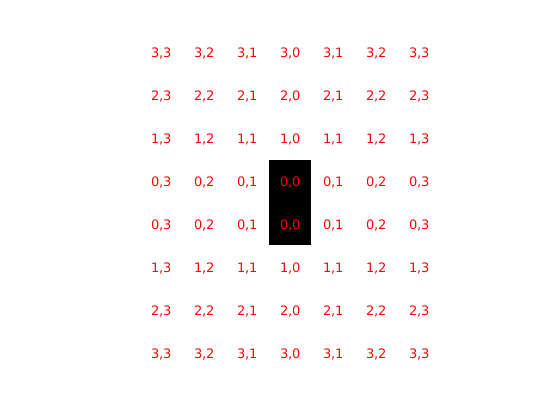

    for j = 1:n

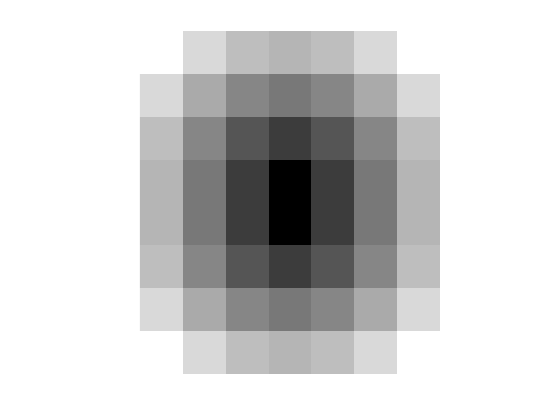

        if(img(i,j))
            if j ~= 1
                val1 = norm(dist{i,j});
                val2 = norm(dist{i,j-1}+[1,0]);
                min_ = min(val1,val2);
                if min_ == val2
                    dist(i,j) = {dist{i,j-1}+[0,1]};
                end
            end

        end
    end
    

**Third Update (C)**

    for j = n:-1:1
        if(img(i,j))
            if(j~=n)
                val1 = norm(dist{i,j});
                val2 = norm(dist{i,j+1}+[1,0]);
                min_ = min(val1,val2);
                if min_ == val2
                    dist(i,j) = {dist{i,j+1}+[0,1]};
                end
            end
        end
    end
end

The complexity of this procedure applied on a binary image of size $W \times H$ is $\mathcal{O}(W \times H)$ since the updating rule can be applied in **constant time**. The upward pass propagates correct Euclidean distance values from the lowest line that contains a point in $\Gamma$. 

*Note: Final values *$EDT^{(t1)}(p)$* in the intermediate distance map are correct and are threrefore not to be updated in a further iteration. *

show_Edist(img,dist)
title("Distance Map after Upward Pass")

## Pass 2 - Downward Sequential Pass

The Euclidean distance map is again scanned line by line from top to bottom. For each line, the upper half of the mask is used via a decomposition in thress sub-masks. 

- The first sub-mask(A) is applied on each pixel of the current line from left to right. 

- The sub-mask (B) is applied on each pixel of the current line from left to right. 

- The sub-mask (C) is applied on each pixel of the current line from right to left.

                                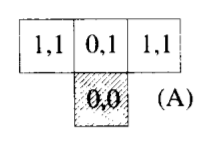   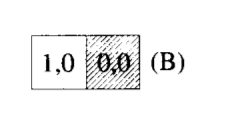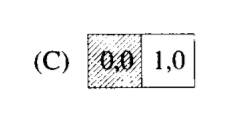

for i = 1:m
    for j = 1:n
        vals = [];
        if(img(i,j))
            if i == 1
                
            elseif j == 1
                for k = 1:2
                    vals = [vals,norm(dist{i-1,j-1+k}+edm_8{3,k+1})];
                end
                [minVal,idx] = min(vals);
                minVal1 = norm(dist{i-1,j-1+idx} + [abs(i-1-i),abs(j-1+idx-j)]);
                minVal2 = norm(dist{i,j});
                if min(minVal1,minVal2)== minVal1
                    dist(i,j) = {dist{i-1,j-1+idx} + [abs(i-1-i),abs(j-1+idx-j)]};
                end
            elseif j == n
                for k = 1:2
                    vals = [vals,norm(dist{i-1,j-2+k}+edm_8{3,k})];
                end
                [minVal,idx] = min(vals);
                minVal1 = norm(dist{i-1,j-2+idx} + [abs(i-1-i),abs(j-2+idx-j)]);
                minVal2 = norm(dist{i,j});
                if min(minVal1,minVal2) == minVal1
                    dist(i,j) = {dist{i-1,j-2+idx} + [abs(i-1-i),abs(j-2+idx-j)]};
                end
                
            else
                for k = 1:3
                    vals = [vals,norm(dist{i-1,j-2+k}+edm_8{3,k})];
                end
                [minVal,idx] = min(vals);
                minVal1 = norm(dist{i-1,j-2+idx} + [abs(i-1-i),abs(j-2+idx-j)]);
                minVal2 = norm(dist{i,j});
                if min(minVal1,minVal2) == minVal1
                    dist(i,j) = {dist{i-1,j-2+idx} + [abs(i-1-i),abs(j-2+idx-j)]};
                end
            end
        end
    end
    for j = 1:n
        if(img(i,j))
            if j ~= 1
                val1 = norm(dist{i,j});
                val2 = norm(dist{i,j-1}+[1,0]);
                min_ = min(val1,val2);
                if min_ == val2
                    dist(i,j) = {dist{i,j-1}+[0,1]};
                end
            end
        end
    end
    for j = n:-1:1
        if(img(i,j))
            if(j~=n)
                val1 = norm(dist{i,j});
                val2 = norm(dist{i,j+1}+[1,0]);
                min_ = min(val1,val2);
                if min_ == val2
                    dist(i,j) = {dist{i,j+1}+[0,1]};
                end
            end
        end
    end
end

show_Edist(img,dist);

Finally, convert the $(x,y)$ data to actual euclidean distance, so that the distance transform could be used in other procedures such as Medial Axis Transform and shortest path computation. 

dMap = zeros(8,7);
for i = 1:m
    for j = 1:n
        dMap(i,j) = norm(dist{i,j});
    end
end
figure
imshow(dMap,[],'InitialMagnification','fit')